# Question #4

**>> Solution**

To solve this problem I will be using the function **power_cal.mlx** to find the power and thrust for the certain airplane given in the instruction.

**>> Code **

## Preparation

weightQ4 = 23105; % weight [lb]
wing_areaQ4 = 505.6; % [ft^2]
ARQ4 = 6.5; % Aspect Ratio
e_oswaldQ4 = 0.87; % Oswald efficiency factor 
C_D0Q4 = 0.032; % zero lift drag ratio
rho_seaLevelQ4 = 2.3769 * 10^(-3); % [slug/ft^3]
rho_5kmQ4 = 1.4244 * 10^(-3); % [slug/ft^3]
KQ4 = 1 / pi / e_oswaldQ4 / ARQ4; 

% velocity
velQ4 = 30:1000; % [ft/s]

## Part (a)

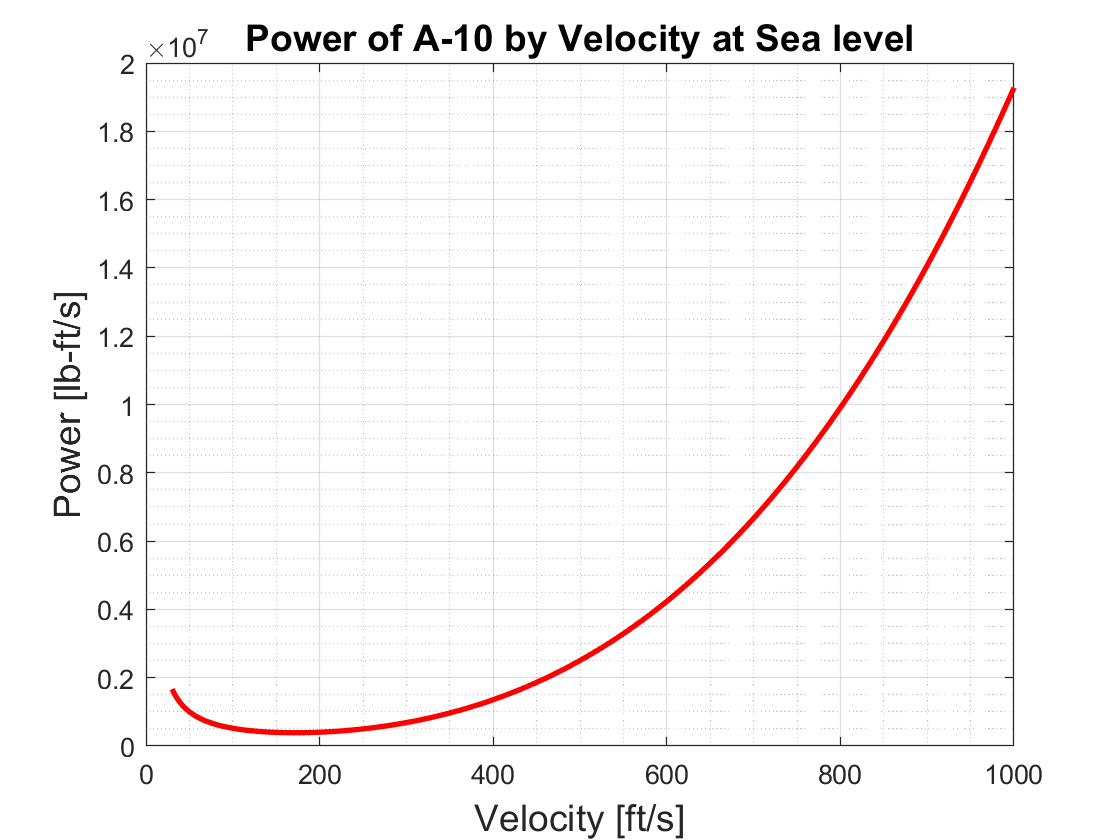

% sea level
[Power_0, Thrust_0] = power_cal(rho_seaLevelQ4, velQ4, wing_areaQ4, C_D0Q4, weightQ4, ARQ4, e_oswaldQ4);

% Plotting
% Adjusting fontsize and linewidth
fontsize = 14;
linewidth = 2;

figure(1)
plot(velQ4, Power_0, '-r', 'LineWidth',linewidth)
title('Power of A-10 by Velocity at Sea level', 'FontSize',fontsize)
xlabel('Velocity [ft/s]', 'FontSize',fontsize)
ylabel('Power [lb-ft/s]', 'FontSize',fontsize)
grid on 
grid minor
box on

## Part (b)

since the static thrust produced by the 2 jet engines are


$${\mathrm{max}\left(T\right)\;=\;T}_A =2\times 9035\;\mathrm{lb}=18070\;\mathrm{lb}\;$$


% Maximum thrust is 
T_A = 18070; 
% The max velocity for this is
V_max_sealevel1 = sqrt((T_A - sqrt(T_A^2 - 4*KQ4*C_D0Q4))/rho_seaLevelQ4/wing_areaQ4/C_D0Q4);
V_max_sealevel2 = sqrt((T_A + sqrt(T_A^2 - 4*KQ4*C_D0Q4))/rho_seaLevelQ4/wing_areaQ4/C_D0Q4);

if V_max_sealevel1 > V_max_sealevel2
    V_max_sealevel = V_max_sealevel1;
else
    V_max_sealevel = V_max_sealevel2;
end

% Print out result
fprintf('The max V at max thrust (%.2f lb)is %.2f ft/s.', T_A, V_max_sealevel);

The max V at max thrust (18070.00 lb)is 969.42 ft/s.

## Part (c)

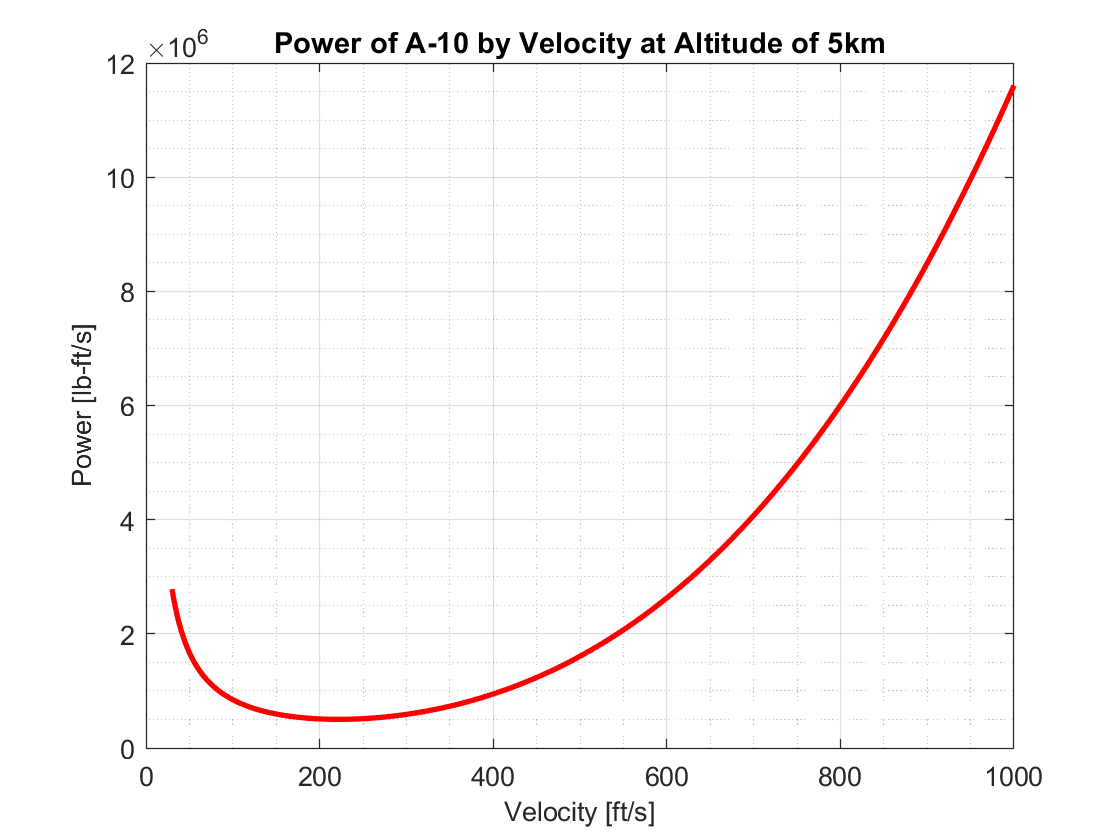


% sea level
[Power_5km, Thrust_5km] = power_cal(rho_5kmQ4, velQ4, wing_areaQ4, C_D0Q4, weightQ4, ARQ4, e_oswaldQ4);

% Plotting
% Adjusting fontsize and linewidth
fontsize = 10;
linewidth = 2;

figure(2)
plot(velQ4, Power_5km, '-r', 'LineWidth',linewidth)
title('Power of A-10 by Velocity at Altitude of 5km', 'FontSize',11)
xlabel('Velocity [ft/s]', 'FontSize',fontsize)
ylabel('Power [lb-ft/s]', 'FontSize',fontsize)
grid on 
grid minor
box on

## Part (d)

since the static thrust produced by the 2 jet engines are


$${\mathrm{max}\left(T\right)\;=\;T}_A =2\times 9035\;\mathrm{lb}=18070\;\mathrm{lb}\;$$



$${\max \left(T\right)\;=\;T}_{A,\mathrm{alt}} =\frac{\rho }{\rho_0 }\;T_A$$


% Maximum thrust is 
T_A_5km = 18070 * rho_5kmQ4 / rho_seaLevelQ4; 
% The max velocity for this is
V_max_5km1 = sqrt((T_A_5km - sqrt(T_A_5km^2 - 4*KQ4*C_D0Q4))/rho_seaLevelQ4/wing_areaQ4/C_D0Q4);
V_max_5km2 = sqrt((T_A_5km + sqrt(T_A_5km^2 - 4*KQ4*C_D0Q4))/rho_seaLevelQ4/wing_areaQ4/C_D0Q4);

if V_max_5km1 > V_max_5km2
    V_max_5km = V_max_5km1;
else
    V_max_5km = V_max_5km2;
end

% Print out result
fprintf('The max V at max thrust (%.2f lb)is %.2f ft/s.', T_A_5km, V_max_5km);

The max V at max thrust (10828.77 lb)is 750.45 ft/s.